# Train PPO Agent for Automatic Parking Valet

This example demonstrates the design of a hybrid controller for an automatic search and parking task. The hybrid controller uses model predictive control (MPC) to follow a reference path in a parking lot and a trained reinforcement learning (RL) agent to perform the parking maneuver.

The automatic parking algorithm in this example executes a series of maneuvers while simultaneously sensing and avoiding obstacles in tight spaces. It switches between an adaptive MPC controller and an RL agent to complete the parking maneuver. The MPC controller moves the vehicle at a constant speed along a reference path while an algorithm searches for an empty parking spot. When a spot is found, the RL Agent takes over and executes a pretrained parking maneuver. Prior knowledge of the environment (the parking lot) including the locations of the empty spots and parked vehicles is available to the controllers.

## Parking Lot

The parking lot is represented by the `ParkingLot` class, which stores information about the ego vehicle, empty parking spots, and static obstacles (parked cars). Each parking spot has a unique index number and an indicator light that is either green (free) or red (occupied). Parked vehicles are represented in black. 

Create a `ParkingLot` object with a free spot at location 7.

freeSpotIdx = 7;
map = ParkingLot(freeSpotIdx);

'ParkingLot' is used in Train PPO Agent for Automatic Parking Valet.

Specify an initial pose $\left(X_0 ,Y_0 ,\theta_0 \right)$ for the ego vehicle. The target pose is determined based on the first available free spot as the vehicle navigates the parking lot.

egoInitialPose = [20, 15, 0];

Compute the target pose for the vehicle using the `createTargetPose` function. The target pose corresponds to the location in `freeSpotIdx`.

egoTargetPose = createTargetPose(map,freeSpotIdx)

## Sensor Modules

The parking algorithm uses camera and lidar sensors to gather information from the environment.

### Camera

The field of view of a camera mounted on the ego vehicle is represented by the area shaded in green in the following figure. The camera has a field of view $\varphi$ bounded by $\pm 60\;\textrm{degrees}$ and a maximum measurement depth $d_{\max }$ of 10 m.

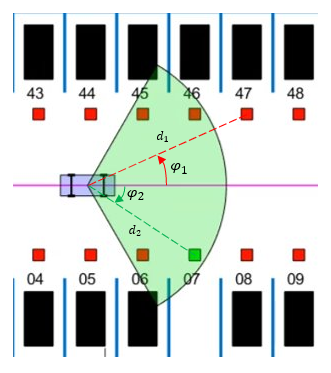

As the ego vehicle moves forward, the camera module senses the parking spots that fall within the field of view and determines whether a spot is free or occupied. For simplicity, this action is implemented using geometrical relationships between the spot locations and the current vehicle pose. A parking spot is within the camera range if $d_i \le d_{\max }$ and $\varphi_{\min } \le \varphi_i \le \varphi_{\max }$, where $d_i$ is the distance to the parking spot and $\varphi_i$ is the angle to the parking spot.

### Lidar

The reinforcement learning agent uses lidar sensor readings to determine the proximity of the ego vehicle to other vehicles in the environment. The lidar sensor in this example is also modeled using geometrical relationships. Lidar distances are measured along 12 line segments that radially emerge from the center of the ego vehicle. When a lidar line intersects an obstacle, it returns the distance of the obstacle from the vehicle. The maximum measurable lidar distance along any line segment is 6 m.

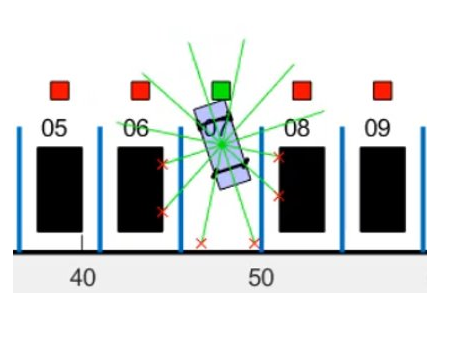

## Auto Parking Valet Model

The parking valet model, including the controllers, ego vehicle, sensors, and parking lot, is implemented in Simulink®.

Load the auto parking valet parameters.

autoParkingValetParams

Open the Simulink model.

mdl = "rlAutoParkingValet";
open_system(mdl)

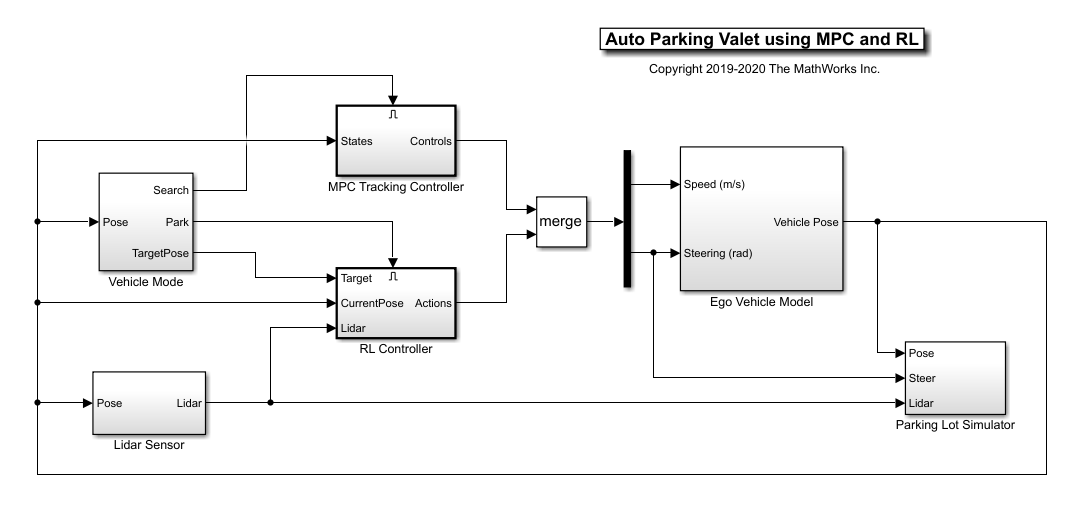

The ego vehicle dynamics in this model are represented by a single-track bicycle model with two inputs: vehicle speed $v$ (m/s) and steering angle $\delta$ (radians). The MPC and RL controllers are placed within Enabled Subsystem blocks that are activated by signals representing whether the vehicle has to search for an empty spot or execute a parking maneuver. The enable signals are determined by the Camera algorithm within the Vehicle Mode subsystem. Initially, the vehicle is in *search* mode and the MPC controller tracks the reference path. When a free spot is found, *park* mode is activated and the RL agent executes the parking maneuver. 

## Adaptive Model Predictive Controller

Create the adaptive MPC controller object for reference trajectory tracking using the `createMPCForParking` script. For more information on adaptive MPC, see [Adaptive MPC](docid:mpc_ug#bujlmiz).

createMPCForParking

## Reinforcement Learning Environment

The environment for training the RL agent is the region shaded in red in the following figure. Due to symmetry in the parking lot, training within this region is sufficient for the policy to adjust to other regions after applying appropriate coordinate transformations to the observations. Using this smaller training region significantly reduces training time compared to training over the entire parking lot. 

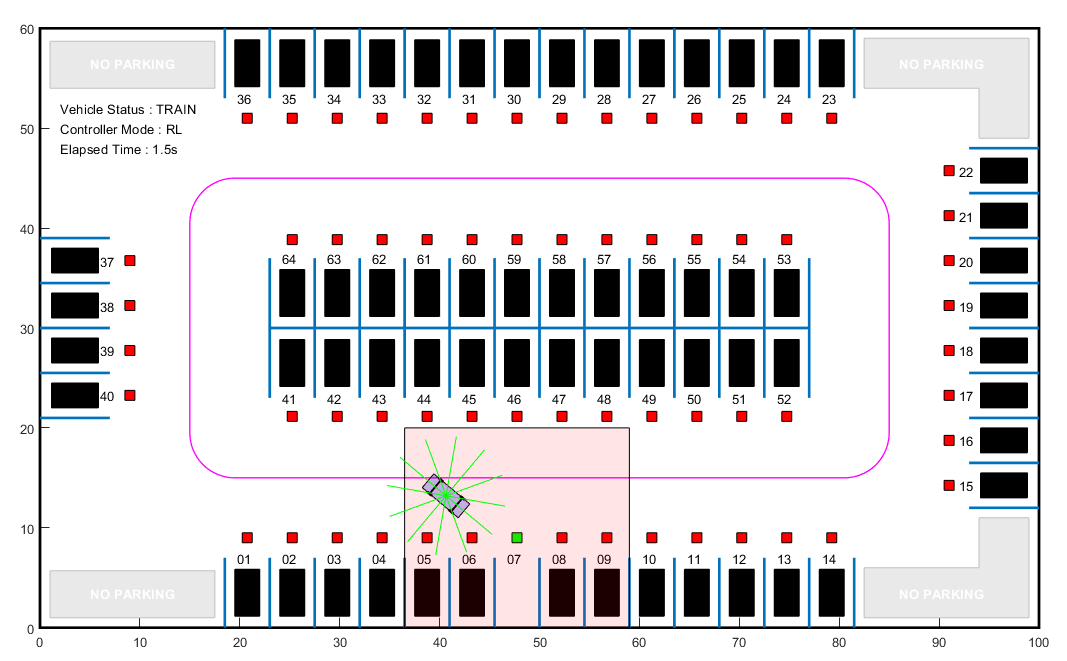

For this environment:

- The training region is a 22.5 m x 20 m space with the target spot at its horizontal center.

- The observations are the position errors $X_e$ and $Y_e$ of the ego vehicle with respect to the target pose, the sine and cosine of the true heading angle $\theta$, and the lidar sensor readings.

- The vehicle speed during parking is a constant 2 m/s.

- The action signals are discrete steering angles that range between +/- 45 degrees in steps of 15 degrees.

- The vehicle is considered parked if the errors with respect to target pose are within specified tolerances of +/- 0.75 m (position) and +/-10 degrees (orientation).

- The episode terminates if the ego vehicle goes out of the bounds of the training region, collides with an obstacle, or parks successfully.

- The reward $r_t$ provided at time *t*, is:

                    
$$r_t =2e^{-\left(0\ldotp 05{X_e }^2 +0\ldotp 04{Y_e }^2 \right)} +0\ldotp 5e^{-40{\theta_e }^2 } -0\ldotp 05\delta^2 +100f_t -50g_t$$


Here, $X_e$, $Y_e$, and $\theta_e$ are the position and heading angle errors of the ego vehicle from the target pose, and $\delta$ is the steering angle. $f_t$ (0 or 1) indicates whether the vehicle has parked and $g_t$ (0 or 1) indicates if the vehicle has collided with an obstacle at time $t$.

The coordinate transformations on vehicle pose $\left(X,Y,\theta \right)$ observations for different parking spot locations are as follows:

- 1-14: no transformation

- 15-22: $\bar{X} =Y,\bar{Y} =-X,\;\bar{\theta} =\theta -\pi /2$

- 23-36: $\bar{X} =100-X,\bar{Y} =60-Y,\;\bar{\theta} =\theta -\pi$

- 37-40: $\bar{X} =60-Y,\bar{Y} =X,\;\bar{\theta} =\theta -3\pi /2$

- 41-52: $\bar{X} =100-X,\bar{Y} =30-Y,\;\bar{\theta} =\theta +\pi$

- 53-64: $\bar{X} =X,\bar{Y} =Y-28,\;\bar{\theta} =\theta$

Create the observation and action specifications for the environment.

numObservations = 16;
obsInfo = rlNumericSpec([numObservations 1]);
obsInfo.Name = "observations";

steerMax = pi/4;
discreteSteerAngles = -steerMax : deg2rad(15) : steerMax;
actInfo = rlFiniteSetSpec(num2cell(discreteSteerAngles));
actInfo.Name = "actions";
numActions = numel(actInfo.Elements);

Create the Simulink environment interface, specifying the path to the RL Agent block.

blk = mdl + "/RL Controller/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

Specify a reset function for training. The `autoParkingValetResetFcn` function resets the initial pose of the ego vehicle to random values at the start of each episode.

env.ResetFcn = @autoParkingValetResetFcn;

For more information on creating Simulink environments, see [`rlSimulinkEnv`](docid:rl_ref#mw_12cc40dc-3191-4a23-af71-1625696c1a14).

## Create Agent

The RL agent in this example is a proximal policy optimization (PPO) agent with a discrete action space. To learn more about PPO agents, see [Proximal Policy Optimization Agents](docid:rl_ug#mw_84b69098-f745-40ba-8aad-c5d46458237f).

Set the random seed generator for reproducibility.

rng(0)

PPO agents use a parametrized value function approximator to estimate the value of the policy. A value-function critic takes the current observation as input and returns a single scalar as output (the estimated discounted cumulative long-term reward for following the policy from the state corresponding to the current observation).

To model the parametrized value function within the critic, use a neural network with one input layer (which receives the content of the observation channel, as specified by `obsInfo`) and one output layer (which returns the scalar value). 

Define the network as an array of layer objects.

criticNet = [
    featureInputLayer(numObservations)
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(1)
    ];


Convert the network to a `dlnetwork` object, and display the number of parameters.

criticNet = dlnetwork(criticNet);
summary(criticNet)

   Initialized: true

   Number of learnables: 35.3k

   Inputs:
      1   'input'   16 features



Create the critic for the PPO agent. For more information, see [`rlValueFunction`](docid:rl_ref#mw_18117070-1c6d-40ba-91f0-0f2cd337918a) and `rlOptimizerOptions`.

critic = rlValueFunction(criticNet,obsInfo);

Policy gradient agents use a parametrized stochastic policy, which for discrete action spaces is implemented by a discrete categorical actor. This actor takes an observation as input and returns as output a random action sampled (among the finite number of possible actions) from a categorical probability distribution.

To model the parametrized policy within the actor, use a neural network with one input layer (which receives the content of the environment observation channel, as specified by `obsInfo`) and one output layer. The output layer must return a vector of probabilities for each possible action, as specified by `actInfo`. 

Define the network as an array of layer objects

actorNet = [
    featureInputLayer(numObservations)
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(numActions)
    softmaxLayer
    ];

Convert the network to a `dlnetwork` object, and display the number of parameters.

actorNet = dlnetwork(actorNet);
summary(actorNet)

   Initialized: true

   Number of learnables: 19.5k

   Inputs:
      1   'input'   16 features



Create a discrete categorical actor for the PPO agent. For more information, see [`rlDiscreteCategoricalActor`](docid:rl_ref#mw_21bebe76-ad01-4680-9c10-59fd51f224b6).

actor = rlDiscreteCategoricalActor(actorNet,obsInfo,actInfo);

Specify training options for the critic and the actor using [`rlOptimizerOptions`](docid:rl_ref#mw_18a712bb-b821-4dd9-a7ad-460ad7f2aa03).

criticOptions = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);
actorOptions = rlOptimizerOptions( ...
    LearnRate=2e-4, ...
    GradientThreshold=1);

Specify the agent options using [`rlPPOAgentOptions`](docid:rl_ref#mw_bf88dbd6-aa46-45cb-89a2-a786a2a9a8cc), include the options for the actor and the critic.

agentOpts = rlPPOAgentOptions(...
    SampleTime=Ts,...
    ActorOptimizerOptions=actorOptions,...
    CriticOptimizerOptions=criticOptions,...
    ExperienceHorizon=200,...
    ClipFactor=0.2,... 
    EntropyLossWeight=0.01,...
    MiniBatchSize=64,...
    NumEpoch=3,...
    AdvantageEstimateMethod="gae",...
    GAEFactor=0.95,...
    DiscountFactor=0.998);

According to these training options, the agent collects experiences until it reaches experience horizon of 200 steps or the episode terminates and then trains from mini-batches of 64 experiences for three epochs. An objective function clip factor of 0.2 improves training stability and a discount factor value of 0.998 encourages long term rewards. Variance in critic the output is reduced by the generalized advantage estimate method with a GAE factor of 0.95.

Create the agent using the actor, the critic, and the agent options object.

agent = rlPPOAgent(actor,critic,agentOpts);

## Train Agent

For this example, you train the agent for a maximum of 10000 episodes, with each episode lasting a maximum of 200 time steps. The training terminates when the maximum number of episodes is reached or the average reward over 100 episodes exceeds 100.  

Specify the options for training using an `rlTrainingOptions` object.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000,...
    MaxStepsPerEpisode=200,...
    ScoreAveragingWindowLength=200,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=80);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;
if doTraining
    trainingStats = train(agent,env,trainOpts);
else
    load('rlAutoParkingValetAgent.mat','agent');
end

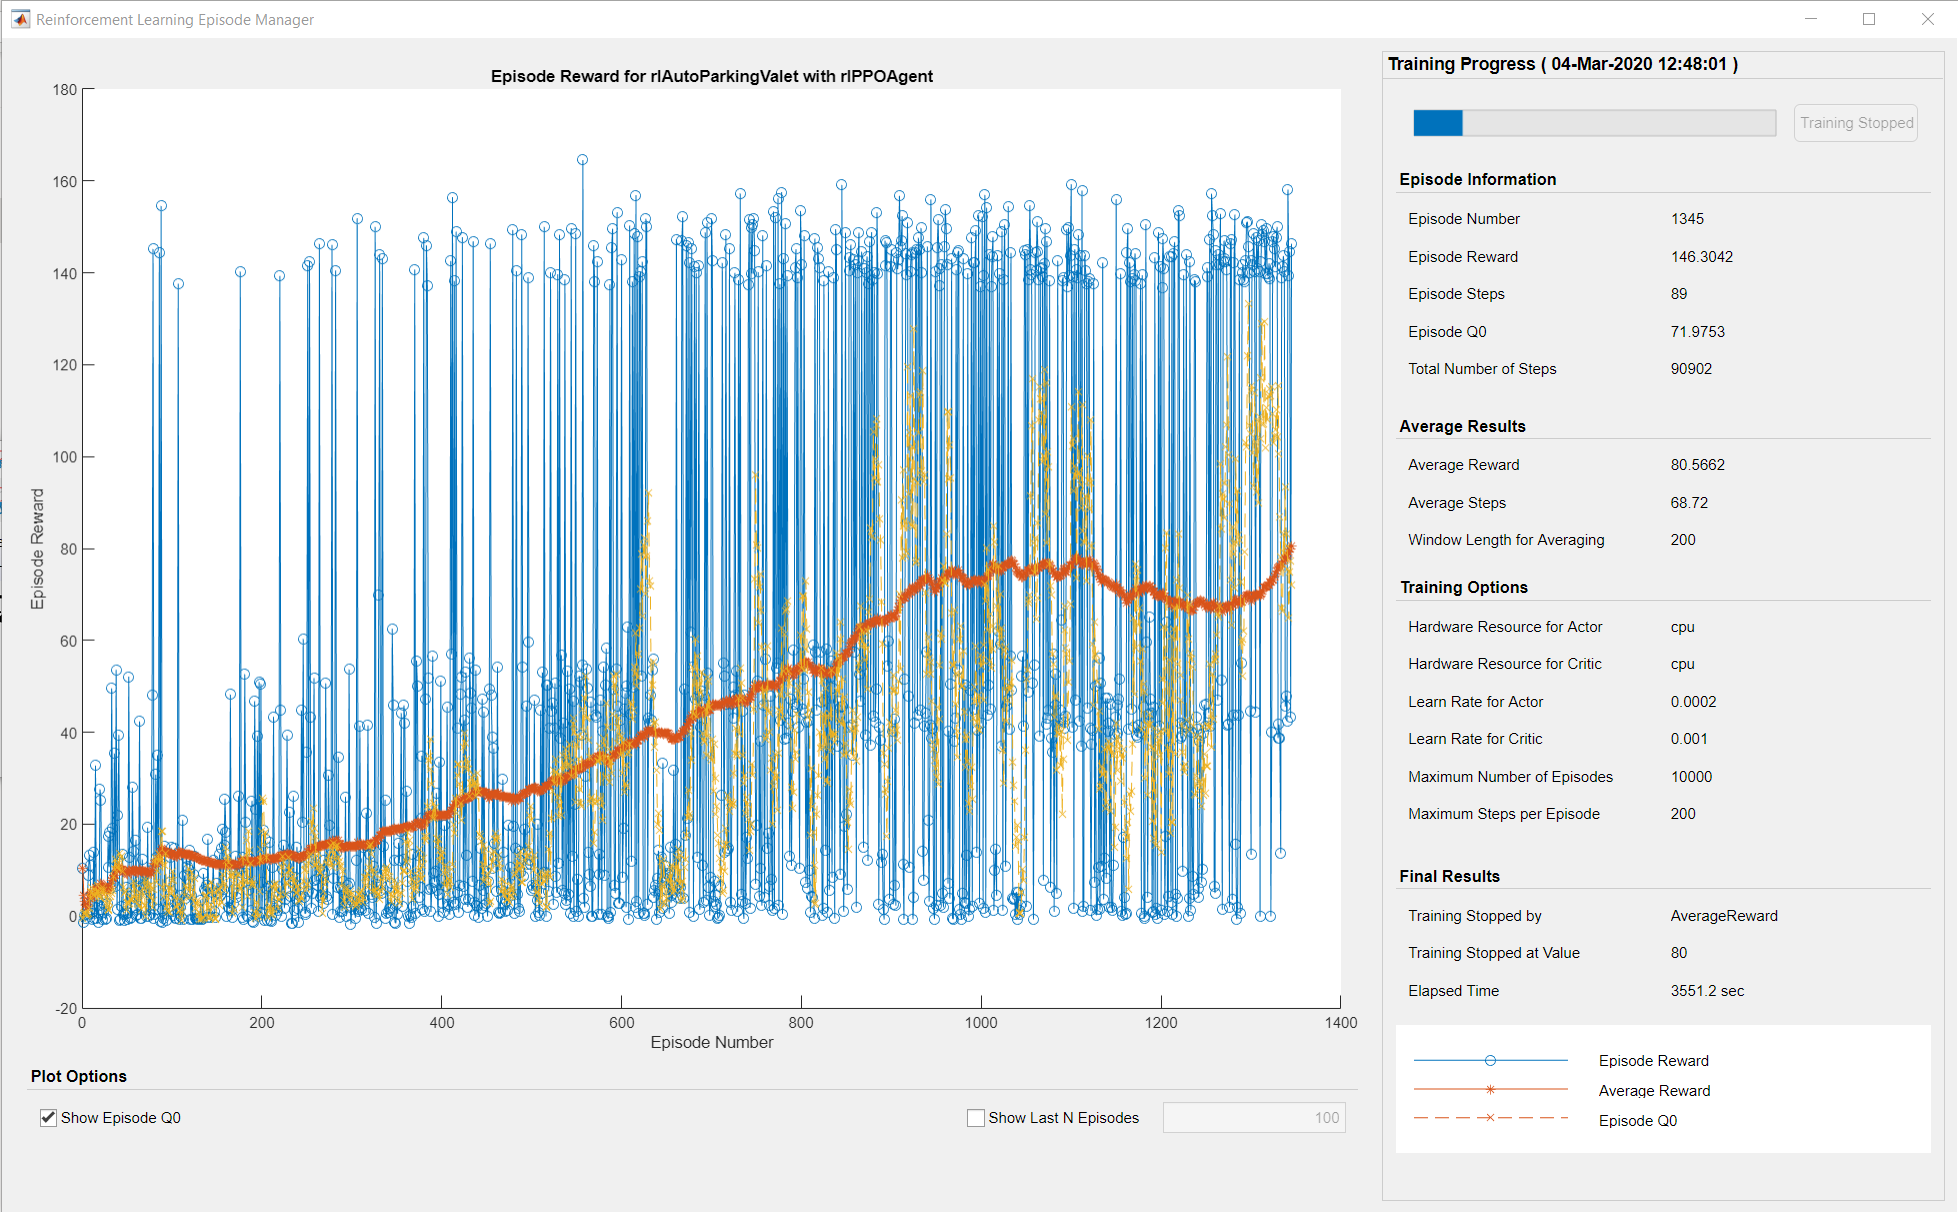

## Simulate Agent

Simulate the model to park the vehicle in the free parking spot. To simulate the vehicle parking in different locations, change the free spot location in the following code.

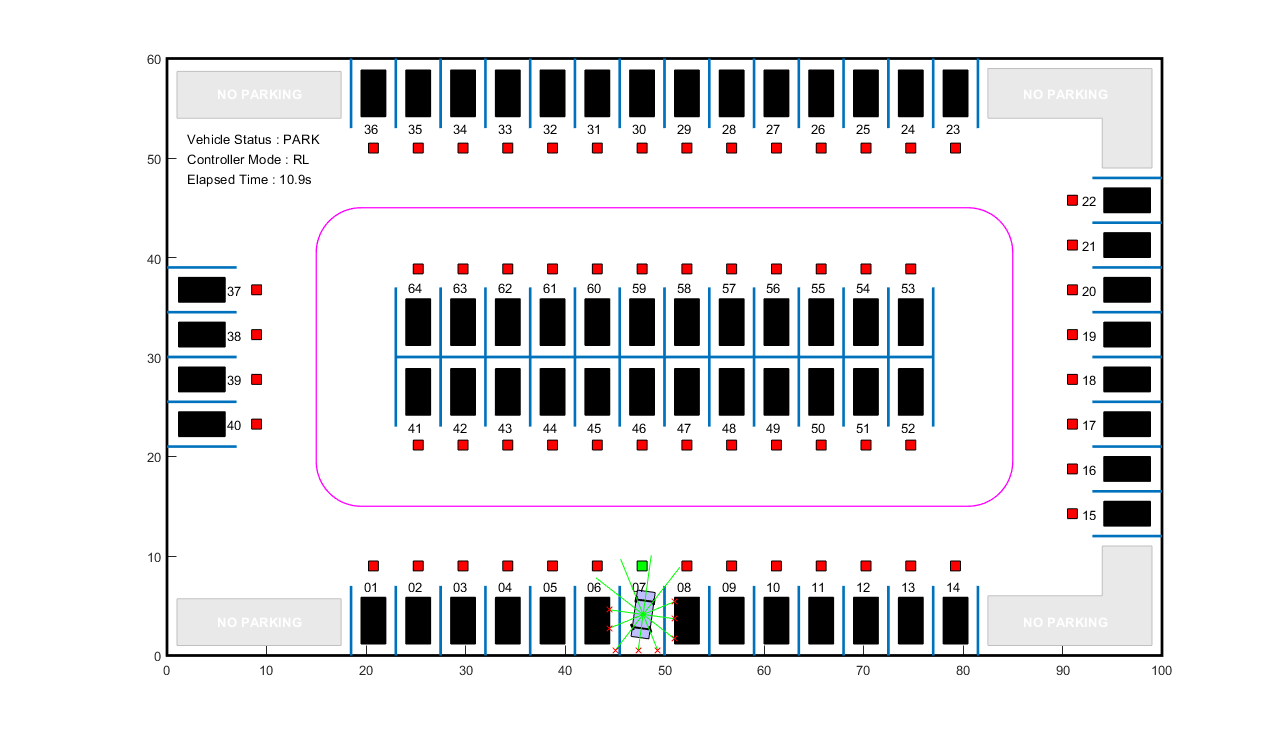

freeSpotIdx = 7;  % free spot location
sim(mdl);

The vehicle reaches the target pose within the specified error tolerances of +/- 0.75 m (position) and +/-10 degrees (orientation).

To view the ego vehicle position and orientation, open the Ego Vehicle Pose scope.

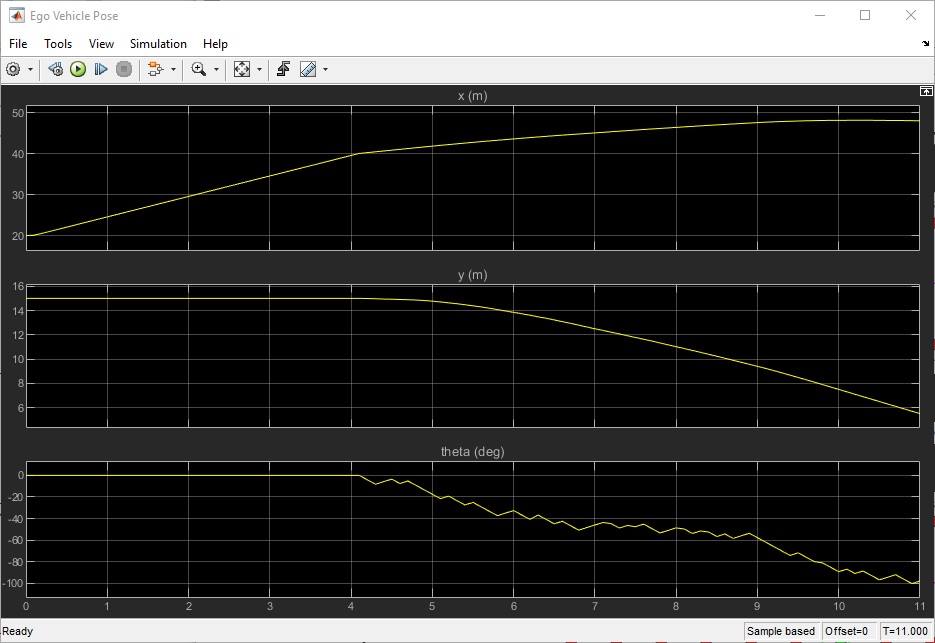

*Copyright 2020-2022 The MathWorks, Inc.*